% Audio Signal Processing: Noise Reduction and Pitch Adjustment
% Load the audio file
fs = 44100; % Sampling rate
t = 0:1/fs:5; % 5 seconds of audio
audio = chirp(t, 0, 5, 1000); % Generate a chirp signal
audiowrite('input_audio.wav', audio, fs); % Save as input_audio.wav

[audio, fs] = audioread('input_audio.wav'); % Replace with your audio file path

% Add noise to the audio
noise_level = 0.1; % افزایش نویز
noisy_audio = audio + noise_level * randn(size(audio));

% Reduce noise using a low-pass filter
cutoff = 3000;
[b, a] = butter(6, cutoff / (fs / 2), 'low');
denoised_audio = filtfilt(b, a, noisy_audio);

% Change pitch and speed
pitch_factor = 4; % Increase pitch by 4 semitones
denoised_pitch_adjusted_audio = shiftPitch(denoised_audio, pitch_factor, fs);

% Save the processed audio
audiowrite('denoised_audio.wav', denoised_audio, fs);

audiowrite('pitch_adjusted_audio.wav', denoised_pitch_adjusted_audio, fs);

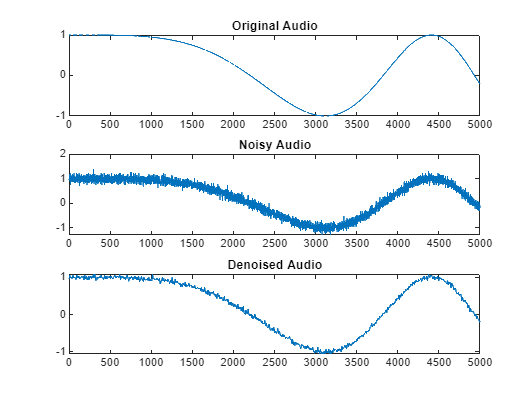


% Visualization
subplot(3, 1, 1);
plot(audio(1:5000));
title('Original Audio');
subplot(3, 1, 2);
plot(noisy_audio(1:5000));
title('Noisy Audio');
subplot(3, 1, 3);
plot(denoised_audio(1:5000));
title('Denoised Audio');


% Pushing the sound to the speaker
sound(audio, fs); % پخش صدای اصلی
pause(length(audio) / fs); % توقف برای پخش کامل

sound(noisy_audio, fs); % پخش صدای نویزدار
pause(length(noisy_audio) / fs); % توقف برای پخش کامل

sound(denoised_audio, fs); % پخش صدای بدون نویز
pause(length(denoised_audio) / fs); % توقف برای پخش کامل

sound(denoised_pitch_adjusted_audio, fs); % پخش صدای تغییر یافته
pause(length(denoised_pitch_adjusted_audio) / fs); % توقف برای پخش کامل

% Helper function to adjust pitch
function pitch_shifted = shiftPitch(audio, pitch_factor, fs)
    pitch_shifted = resample(audio, round(fs * 2^(pitch_factor/12)), fs);
end

